%--------------------------
clear all;
%cd('C:\Users\xy123\Matlab\Nlab_matlab/exp3_analysis/');

%-----------------------------------
% Acitivate at exp3_analysis
resultpath = "./results/";
ana_result = "analysis/";
Datapath = "./data/";

MatNames1 = {'cu0025', 'cu0129', 'pla0075', 'pla0225'};
MatNames2 = {'cu_0.025', 'cu_0.129', 'pla_0.075', 'pla_0.225'};
MatNames3 = {'cu-0.025', 'cu-0.129', 'pla-0.075', 'pla-0.225'};
HDRNames_15 = [19, 39, 78, 80, 102, 125, 152, 203, 226, 227, 230, 232, 243, 278, 281];
HDRNames_30 = [5,19,34,39,42,43,78,80,102,105,125,152,164,183,198,201,202,203,209,222,226,227,230,232,243,259,272,278,281,282];
HDRNum_15 = [2,4,7,8,9,11,12,18,21,22,23,24,25,28,29];
HDRNum_30 = [1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27,28,29,30];
ShapeNames = {'sphere','bunny','dragon','boardA','boardB','boardC'};

% load data
load(strcat(Datapath,'Exp1Mi_data.mat'));
Exp1MiHMP15 = Exp1MiRowHMP;
Exp1MiHM15 = Exp1MiZsHM;
Exp1MiH15 = Exp1MiZsH;
err_Exp1MiHM15 = error_Exp1MiZsHM;
err_Exp1MiH15 = error_Exp1MiZsH;

load(strcat(Datapath,'Exp2Mi_data.mat'));
Exp2MiHMPT15 = Exp2MiRowHMPT;
Exp2MiHM15 = Exp2MiZsHM;
Exp2MiH15 = Exp2MiZsH;
err_Exp2MiHM15 = error_Exp2MiZsHM;
err_Exp2MiH15 = error_Exp2MiZsH;

load(strcat(Datapath,'Exp1Th_data.mat'));
Exp1ThHMP15 = Exp1ThRowHMP;
Exp1ThHM15 = Exp1ThZsHM;
Exp1ThH15 = Exp1ThZsH;
err_Exp1ThHM15 = error_Exp1ThZsHM;
err_Exp1ThH15 = error_Exp1ThZsH;

load(strcat(Datapath,'Exp2Th_data.mat'));
Exp2ThHMPT15 = Exp2ThRowHMPT;
Exp2ThHM15 = Exp2ThZsHM;
Exp2ThH15 = Exp2ThZsH;
err_Exp2ThHM15 = error_Exp2ThZsHM;
err_Exp2ThH15 = error_Exp2ThZsH;

load(strcat(Datapath,'Exp3_data.mat'));
Exp3HMSPT_Row = RowHMSPT;
Exp3HMS_Row = RowHMS;
Exp3HS_Row = RowHS;
Exp3HM_Row = RowHM;
Exp3H_Row = RowH;
Exp3HMS = ZsHMS;
Exp3HS = ZsHS;
Exp3HM = ZsHM;
Exp3H = ZsH;
Exp3HM15 = Zs15bnyHM;
Exp3H15 = Zs15bnyH;
err_Exp3HMS = error_ZsHMS;
err_Exp3HM = error_ZsHM;
err_Exp3HS = error_ZsHS;
err_Exp3H = error_ZsH;
err_Exp3HM15 = error_HM15;
err_Exp3H15 = error_H15;

load(strcat(Datapath,'Exp4_data.mat'));
Exp4HMSPT_Row = RowHMSPT;
Exp4HMS_Row = RowHMS;
Exp4HS_Row = RowHS;
Exp4HM_Row = RowHM;
Exp4H_Row = RowH;
Exp4HMS = ZsHMS;
Exp4HS = ZsHS;
Exp4HM = ZsHM;
Exp4H = ZsH;
Exp4HM15 = Zs15bnyHM;
Exp4H15 = Zs15bnyH;
err_Exp4HMS = error_ZsHMS;
err_Exp4HM = error_ZsHM;
err_Exp4HS = error_ZsHS;
err_Exp4H = error_ZsH;
err_Exp4HM15 = error_HM15;
err_Exp4H15 = error_H15;

load(strcat(Datapath,'Inoue_data.mat'));
InoueHMSPT_Row = RowHMSPT;
InoueHMS_Row = RowHMS;
InoueHS_Row = RowHS;
InoueHM_Row = RowHM;
InoueH_Row = RowH;
InoueHMSPT = RowHMSPT;
InoueHMS = ZsHMS;
InoueHM = ZsHM;
InoueHS = ZsHS;
InoueH = ZsH;
InoueHM15 = Zs15bnyHM;
InoueH15 = Zs15bnyH;
err_InoueHMS = error_ZsHMS;
err_InoueHM = error_ZsHM;
err_InoueHS = error_ZsHS;
err_InoueH = error_ZsH;
err_InoueHM15 = error_HM15;
err_InoueH15 = error_H15;

load(strcat(Datapath,'lummodel_data.mat'));
LumModelH = lummodelH;
Error_LumModelH = zeros(size(LumModelH));
LumModelNormH = lummodelNormH;
LumModelZsH = lummodelZsH;

load(strcat(Datapath,'objmodel_data.mat'));
ObjModelHMS = objmodelZsHMS;
ObjModelNormHMS = objmodelNormHMS;
ObjModelH = objmodelZsH;
ObjModelNormH = objmodelNormH;
ObjModelHS = objmodelZsHS;
ObjModelHM = objmodelZsHM;

%---------------------------------------
% Exp3 vs Exp4 GRI Student H
%---------------------------------------
amp = 1.5;
coef_list = zeros(size(Exp3H));
slop_list = zeros(size(Exp3H));
threshold = 2.0;

%散布図
figure;
graphtitle = sprintf('VRON GRI VS VROFF GRI');
Outlinear_Points_HMS = Outlinear_Detection(Exp3H(:),Exp4H(:),threshold,coef_list,slop_list, ...
    'VRON GRI','VROFF GRI',graphtitle,HDRNum_30,amp);

    30     1


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate        SE          tStat         pValue  
                   __________    ________    ___________    __________

    (Intercept)    -2.338e-15      0.0525    -4.4534e-14             1
    x1                0.95925    0.053397         17.964    6.6385e-17


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.288
決定係数: 0.92、自由度調整済み決定係数: 0.917
F 統計量 - 定数モデルとの比較: 323、p 値は 6.64e-17 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 2, VR GRI: -1.25, 2D GRI: -0.58, Student化残差: 2.48
点番号: 5, VR GRI: 0.95, 2D GRI: 0.38, Student化残差: -2.01
点番号: 10, VR GRI: 0.99, 2D GRI: 1.51, Student化残差: 2.12


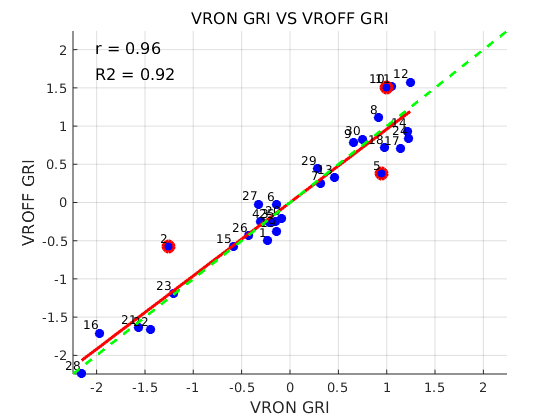

plotname = strcat(ana_result, '/VRONvsVROFF_GRI_Student_HDR_Coef.jpg');
saveas(gcf, plotname);

線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate         SE          tStat         pValue  
                   ___________    ________    ___________    __________

    (Intercept)    -1.9022e-15    0.096499    -1.9713e-14             1
    x1                 0.85456    0.098148         8.7068    1.8642e-09


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.529
決定係数: 0.73、自由度調整済み決定係数: 0.721
F 統計量 - 定数モデルとの比較: 75.8、p 値は 1.86e-09 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 2, VR GRI: -2.55, 2D GRI: -1.24, Student化残差: 2.19
点番号: 29, VR GRI: 0.18, 2D GRI: -1.47, Student化残差: -3.82


Outlinear_Points_HMS =      0
     1
     0
     0
     0
     0
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate       SE         tStat         pValue  
                   __________    _______    __________    __________

    (Intercept)    1.4711e-15     0.1315    1.1187e-14             1
    x1                0.70647    0.13375         5.282    1.2834e-05


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.72
決定係数: 0.499、自由度調整済み決定係数: 0.481
F 統計量 - 定数モデルとの比較: 27.9、p 値は 1.28e-05 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 17, VR GRI: 0.88, 2D GRI: -0.91, Student化残差: -2.36


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                   Estimate        SE         tStat         pValue  
                   _________    ________    __________    __________

    (Intercept)    4.726e-16    0.081787    5.7784e-15             1
    x1               0.89791    0.083185        10.794    1.7353e-11


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.448
決定係数: 0.806、自由度調整済み決定係数: 0.799
F 統計量 - 定数モデルとの比較: 117、p 値は 1.74e-11 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 2, VR GRI: -1.50, 2D GRI: -0.47, Student化残差: 2.21
点番号: 28, VR GRI: -2.18, 2D GRI: -2.83, Student化残差: -2.35


Outlinear_Points_HMS =      0
     1
     0
     0
     0
     0
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate       SE        tStat        pValue  
                   __________    _______    ________    __________

    (Intercept)    5.1002e-16    0.13935    3.66e-15             1
    x1                0.66147    0.14173      4.6671    6.8894e-05


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.763
決定係数: 0.438、自由度調整済み決定係数: 0.417
F 統計量 - 定数モデルとの比較: 21.8、p 値は 6.89e-05 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 6, VR GRI: 0.80, 2D GRI: -0.97, Student化残差: -2.15
点番号: 27, VR GRI: -1.43, 2D GRI: 0.58, Student化残差: 2.26
点番号: 29, VR GRI: 1.12, 2D GRI: 2.19, Student化残差: 2.09


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     1
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate        SE         tStat         pValue  
                   __________    ________    __________    __________

    (Intercept)    9.0509e-17    0.097701    9.2639e-16             1
    x1                0.85059    0.099372        8.5597    2.6482e-09


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.535
決定係数: 0.724、自由度調整済み決定係数: 0.714
F 統計量 - 定数モデルとの比較: 73.3、p 値は 2.65e-09 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 6, VR GRI: -1.04, 2D GRI: -2.05, Student化残差: -2.44


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     1
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate        SE         tStat         pValue  
                   __________    ________    __________    __________

    (Intercept)    2.4524e-16    0.098684    2.4851e-15             1
    x1                 0.8473     0.10037        8.4417    3.5165e-09


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.541
決定係数: 0.718、自由度調整済み決定係数: 0.708
F 統計量 - 定数モデルとの比較: 71.3、p 値は 3.52e-09 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 12, VR GRI: 1.56, 2D GRI: 3.12, Student化残差: 4.66


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


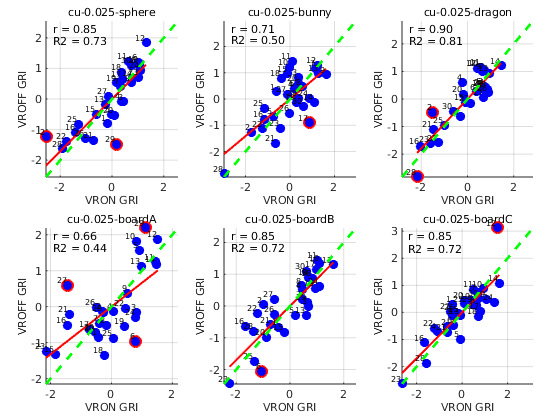

線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate        SE         tStat        pValue  
                   __________    ________    _________    __________

    (Intercept)    6.3843e-16    0.077451    8.243e-15             1
    x1                0.90898    0.078775       11.539    3.7331e-12


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.424
決定係数: 0.826、自由度調整済み決定係数: 0.82
F 統計量 - 定数モデルとの比較: 133、p 値は 3.73e-12 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 18, VR GRI: 0.95, 2D GRI: 1.68, Student化残差: 2.11
点番号: 20, VR GRI: 0.43, 2D GRI: -0.85, Student化残差: -3.52


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate       SE         tStat        pValue  
                   __________    _______    _________    __________

    (Intercept)    1.1706e-15    0.11443    1.023e-14             1
    x1                0.78787    0.11638       6.7695    2.3703e-07


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.627
決定係数: 0.621、自由度調整済み決定係数: 0.607
F 統計量 - 定数モデルとの比較: 45.8、p 値は 2.37e-07 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 28, VR GRI: -2.96, 2D GRI: -3.72, Student化残差: -3.10


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate        SE          tStat         pValue  
                   ___________    _______    ___________    __________

    (Intercept)    -1.5127e-16    0.10826    -1.3973e-15             1
    x1                 0.81272    0.11011         7.3809    4.8849e-08


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.593
決定係数: 0.661、自由度調整済み決定係数: 0.648
F 統計量 - 定数モデルとの比較: 54.5、p 値は 4.88e-08 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 17, VR GRI: 1.13, 2D GRI: -0.24, Student化残差: -2.16
点番号: 19, VR GRI: 0.83, 2D GRI: -0.80, Student化残差: -2.87
点番号: 28, VR GRI: -2.28, 2D GRI: -3.15, Student化残差: -2.73


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate       SE         tStat        pValue  
                   __________    _______    _________    __________

    (Intercept)    6.9083e-16    0.14443    4.783e-15             1
    x1                0.62908     0.1469       4.2822    0.00019632


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.791
決定係数: 0.396、自由度調整済み決定係数: 0.374
F 統計量 - 定数モデルとの比較: 18.3、p 値は 0.000196 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 29, VR GRI: 0.58, 2D GRI: 2.02, Student化残差: 2.30


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate       SE         tStat         pValue  
                   __________    _______    __________    __________

    (Intercept)    9.0587e-16    0.10436    8.6805e-15             1
    x1                0.82738    0.10614        7.7952    1.7187e-08


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.572
決定係数: 0.685、自由度調整済み決定係数: 0.673
F 統計量 - 定数モデルとの比較: 60.8、p 値は 1.72e-08 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 6, VR GRI: -0.88, 2D GRI: -2.14, Student化残差: -2.86


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     1
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                   Estimate       SE         tStat         pValue  
                   _________    _______    __________    __________

    (Intercept)    1.315e-15    0.13802    9.5278e-15             1
    x1               0.66948    0.14038        4.7691    5.2145e-05


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.756
決定係数: 0.448、自由度調整済み決定係数: 0.429
F 統計量 - 定数モデルとの比較: 22.7、p 値は 5.21e-05 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 17, VR GRI: 0.80, 2D GRI: -1.53, Student化残差: -3.26


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


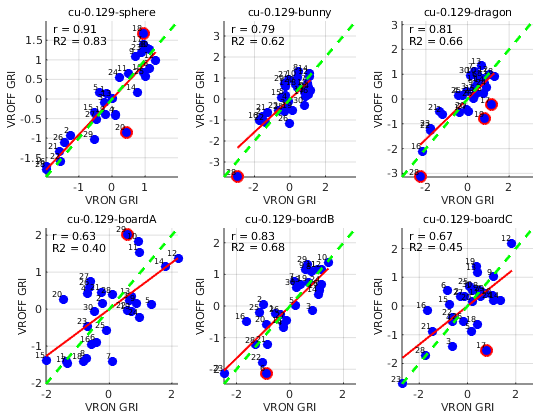

線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate         SE          tStat         pValue  
                   ___________    ________    ___________    __________

    (Intercept)    -1.2981e-17    0.071978    -1.8035e-16             1
    x1                 0.92192    0.073208         12.593    4.7334e-13


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.394
決定係数: 0.85、自由度調整済み決定係数: 0.845
F 統計量 - 定数モデルとの比較: 159、p 値は 4.73e-13 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 14, VR GRI: 1.04, 2D GRI: -0.10, Student化残差: -3.24


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate         SE         tStat         pValue  
                   ___________    ________    __________    __________

    (Intercept)    -3.6012e-17    0.094373    -3.816e-16             1
    x1                 0.86141    0.095986        8.9743    9.9188e-10


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.517
決定係数: 0.742、自由度調整済み決定係数: 0.733
F 統計量 - 定数モデルとの比較: 80.5、p 値は 9.92e-10 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 2, VR GRI: -1.74, 2D GRI: -0.15, Student化残差: 3.26


Outlinear_Points_HMS =      0
     1
     0
     0
     0
     0
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate        SE         tStat         pValue  
                   __________    ________    __________    __________

    (Intercept)    4.2292e-16    0.073468    5.7565e-15             1
    x1                0.91851    0.074724        12.292    8.4315e-13


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.402
決定係数: 0.844、自由度調整済み決定係数: 0.838
F 統計量 - 定数モデルとの比較: 151、p 値は 8.43e-13 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 29, VR GRI: 0.28, 2D GRI: -0.63, Student化残差: -2.45


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                   Estimate       SE         tStat         pValue  
                   _________    _______    __________    __________

    (Intercept)    1.571e-15     0.1236    1.2711e-14             1
    x1               0.74665    0.12571        5.9394    2.1547e-06


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.677
決定係数: 0.557、自由度調整済み決定係数: 0.542
F 統計量 - 定数モデルとの比較: 35.3、p 値は 2.15e-06 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 6, VR GRI: -1.59, 2D GRI: 0.37, Student化残差: 2.73
点番号: 10, VR GRI: 0.50, 2D GRI: 2.02, Student化残差: 2.78
点番号: 29, VR GRI: 0.59, 2D GRI: 2.09, Student化残差: 2.77


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     1
     0
     0
     0
     1


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                   Estimate       SE         tStat         pValue  
                   ________    ________    __________    __________

    (Intercept)    2.99e-16    0.078589    3.8046e-15             1
    x1              0.90615    0.079932        11.336    5.6317e-12


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.43
決定係数: 0.821、自由度調整済み決定係数: 0.815
F 統計量 - 定数モデルとの比較: 129、p 値は 5.63e-12 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 5, VR GRI: 0.76, 2D GRI: -0.53, Student化残差: -3.42
点番号: 6, VR GRI: -1.81, 2D GRI: -0.83, Student化残差: 2.15


Outlinear_Points_HMS =      0
     0
     0
     0
     1
     1
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate        SE         tStat         pValue  
                   __________    ________    __________    __________

    (Intercept)    7.4546e-16    0.059694    1.2488e-14             1
    x1                0.94699    0.060714        15.597    2.4483e-15


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.327
決定係数: 0.897、自由度調整済み決定係数: 0.893
F 統計量 - 定数モデルとの比較: 243、p 値は 2.45e-15 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 18, VR GRI: 0.78, 2D GRI: 0.01, Student化残差: -2.50


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


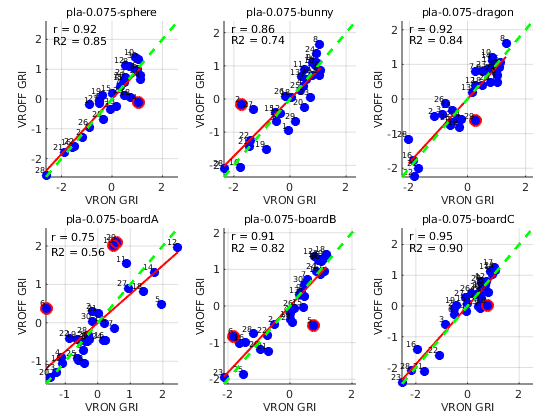

線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate         SE          tStat        pValue 
                   ___________    ________    ___________    ________

    (Intercept)    -2.1652e-16    0.081845    -2.6455e-15           1
    x1                 0.89776    0.083244         10.785    1.77e-11


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.448
決定係数: 0.806、自由度調整済み決定係数: 0.799
F 統計量 - 定数モデルとの比較: 116、p 値は 1.77e-11 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 1, VR GRI: 0.76, 2D GRI: -0.73, Student化残差: -3.98
点番号: 3, VR GRI: -0.70, 2D GRI: 0.35, Student化残差: 2.43


Outlinear_Points_HMS =      1
     0
     1
     0
     0
     0
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate        SE         tStat         pValue  
                   __________    ________    __________    __________

    (Intercept)    4.2695e-16    0.098567    4.3315e-15             1
    x1                 0.8477     0.10025        8.4556    3.4006e-09


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.54
決定係数: 0.719、自由度調整済み決定係数: 0.709
F 統計量 - 定数モデルとの比較: 71.5、p 値は 3.4e-09 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 1, VR GRI: 1.04, 2D GRI: -0.62, Student化残差: -3.37
点番号: 2, VR GRI: -1.32, 2D GRI: 0.28, Student化残差: 3.12


Outlinear_Points_HMS =      1
     1
     0
     0
     0
     0
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate        SE         tStat         pValue  
                   __________    ________    __________    __________

    (Intercept)    1.3512e-16    0.074585    1.8116e-15             1
    x1                 0.9159     0.07586        12.073    1.2897e-12


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.409
決定係数: 0.839、自由度調整済み決定係数: 0.833
F 統計量 - 定数モデルとの比較: 146、p 値は 1.29e-12 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 1, VR GRI: 0.86, 2D GRI: -0.04, Student化残差: -2.22
点番号: 7, VR GRI: -0.91, 2D GRI: -0.06, Student化残差: 2.09
点番号: 29, VR GRI: -0.62, 2D GRI: -1.38, Student化残差: -2.17


Outlinear_Points_HMS =      1
     0
     0
     0
     0
     0
     1
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate        SE         tStat         pValue  
                   __________    ________    __________    __________

    (Intercept)    1.5037e-15    0.095931    1.5675e-14             1
    x1                0.85641    0.097571        8.7774    1.5769e-09


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.525
決定係数: 0.733、自由度調整済み決定係数: 0.724
F 統計量 - 定数モデルとの比較: 77、p 値は 1.58e-09 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 18, VR GRI: 2.20, 2D GRI: 2.88, Student化残差: 2.26
点番号: 21, VR GRI: 0.16, 2D GRI: -1.05, Student化残差: -2.52


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate        SE         tStat         pValue  
                   __________    ________    __________    __________

    (Intercept)    1.6028e-16    0.070185    2.2836e-15             1
    x1                0.92591    0.071385        12.971    2.3269e-13


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.384
決定係数: 0.857、自由度調整済み決定係数: 0.852
F 統計量 - 定数モデルとの比較: 168、p 値は 2.33e-13 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 5, VR GRI: 1.24, 2D GRI: 0.27, Student化残差: -2.65


Outlinear_Points_HMS =      0
     0
     0
     0
     1
     0
     0
     0
     0
     0


線形回帰モデル: 
    y ~ 1 + x1

推定された係数: 
                    Estimate         SE          tStat         pValue  
                   ___________    ________    ___________    __________

    (Intercept)    -1.4594e-15    0.066402    -2.1979e-14             1
    x1                 0.93396    0.067537         13.829    4.8923e-14


観測数: 30、誤差の自由度: 28
平方根平均二乗誤差: 0.364
決定係数: 0.872、自由度調整済み決定係数: 0.868
F 統計量 - 定数モデルとの比較: 191、p 値は 4.89e-14 です

--- 検出された外れ値（Student化残差の絶対値が2.0を超える点）---
点番号: 12, VR GRI: 0.91, 2D GRI: -0.03, Student化残差: -2.77


Outlinear_Points_HMS =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


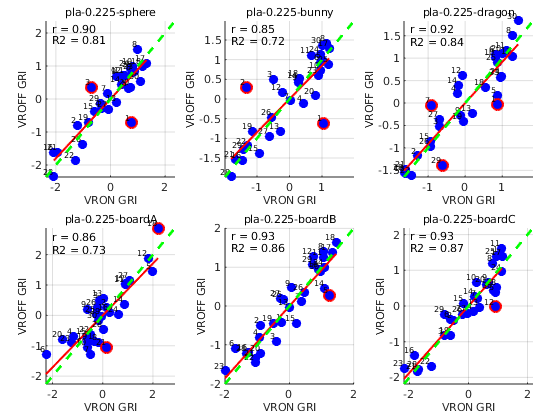

%-----------------------------------
% Exp3 vs Exp4 GRI Student HMS
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1;
threshold = 2.0;
Outlinear_Points = zeros(30,1);

for mat = 1:size(Exp3HMS,2)
    figure;
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;

        graphtitle = sprintf('%s-%s',string(MatNames3(mat)),string(ShapeNames(shape)));
        Outlinear_Points_HMS = Outlinear_Detection(Exp3HMS(:,mat,shape),Exp4HMS(:,mat,shape),threshold,coef_list,slop_list, ...
            'VRON GRI','VROFF GRI',graphtitle,HDRNum_30,amp)
        Outlinear_Points = Outlinear_Points + Outlinear_Points_HMS;
    end
    plotname = sprintf('%s/VRONvsVROFF_GRI_Student_MS_%s_Coef.jpg',ana_result,string(MatNames3(mat)));
    saveas(gcf, plotname);
end

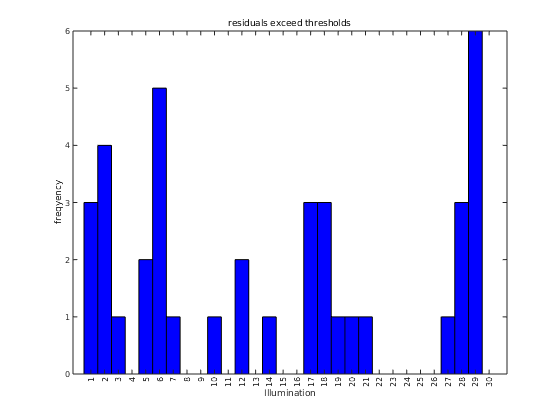



% bar graph
x = 1:length(HDRNum_30);
figure;
bar_1 = bar(x, Outlinear_Points, 1, 'FaceColor', 'b');
set(gca, 'XTick', x);
xticklabels(HDRNum_30);
xtickangle(90);
set(gca,'FontSize',6*amp);
title('residuals exceed thresholds');
xlabel('Illumination');
ylabel('freqyency');
plotname = sprintf('%s/Outlinear_HMS_Hist.jpg',ana_result);
saveas(gcf, plotname);

%---------------------------------------
% Exp3 vs Exp4 Glossiness H
%---------------------------------------
amp = 1.5;
coef_list = zeros(size(Exp3H_Row));
slop_list = zeros(size(Exp3H_Row));

%散布図
figure;
graphtitle = sprintf('Exp3 GRI VS Exp4 GRI');
Analysis_plot1(Exp3H_Row(:),Exp4H_Row(:),coef_list,slop_list, ...
    'VRON Gloss','VROFF Gloss',graphtitle,HDRNum_30,amp,1)
plotname = strcat(ana_result, '/VRONvsVROFF_Gloss_HDR_Coef.jpg');
saveas(gcf, plotname);

%histgram
figure;
Analysis_histgram1(Exp3H_Row(:),err_Exp3H(:),Exp4H_Row(:),err_Exp4H(:), ...
    'HDR',HDRNum_30,'Normalized z-score',graphtitle,amp)
plotname = strcat(ana_result, '/VRONvsVROFF_Gloss_HDR_Hist.jpg');
saveas(gcf, plotname);

%---------------------------------------
% Exp3 vs Exp4 Glossiness HM
%---------------------------------------
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;

figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM_Row,2)
    nexttile;
    Analysis_plot1(Exp3HM_Row(:,mat),Exp4HM_Row(:,mat),coef_list,slop_list, ...
        'VRON Gloss','VROFF Gloss',string(MatNames3(mat)),HDRNum_30,amp,predim)
end
plotname = strcat(ana_result, '/VRONvsVROFF_Gloss_Mat_Coef.jpg');
saveas(gcf, plotname);

%histgram
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM_Row,2)
    nexttile;
    Analysis_histgram1(Exp3HM_Row(:,mat),err_Exp3HM(:,mat),Exp4HM_Row(:,mat),err_Exp4HM(:,mat), ...
        'HDR',HDRNum_30,'Normalized z-score',string(MatNames3(mat)),amp)
end
plotname = strcat(ana_result, '/VRONvsVROFF_Gloss_Mat_Hist.jpg');
saveas(gcf, plotname);

%-----------------------------------
% Exp3 vs Exp4 Gloss HS
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;

figure;
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS_Row,2)
    nexttile;
    Analysis_plot1(Exp3HS_Row(:,shape),Exp4HS_Row(:,shape),coef_list,slop_list, ...
        'VRON Gloss','VROFF Gloss',string(ShapeNames(shape)),HDRNum_30,amp,predim);
end
plotname = strcat(ana_result, '/VRONvsVROFF_Gloss_Shape_Coef.jpg');
saveas(gcf, plotname);


%histgram1
figure('Position',[50,50,1300,840]);
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS_Row,2)
    nexttile;
    Analysis_histgram1(Exp3HS_Row(:,shape),err_Exp3HS(:,shape),Exp4HS_Row(:,shape),err_Exp4HS(:,shape), ...
        'HDR',HDRNum_30,'Normalized z-score',string(ShapeNames(shape)),amp)
end
plotname = strcat(ana_result, '/VRONvsVROFF_Gloss_Shape_Hist.jpg');
saveas(gcf, plotname);

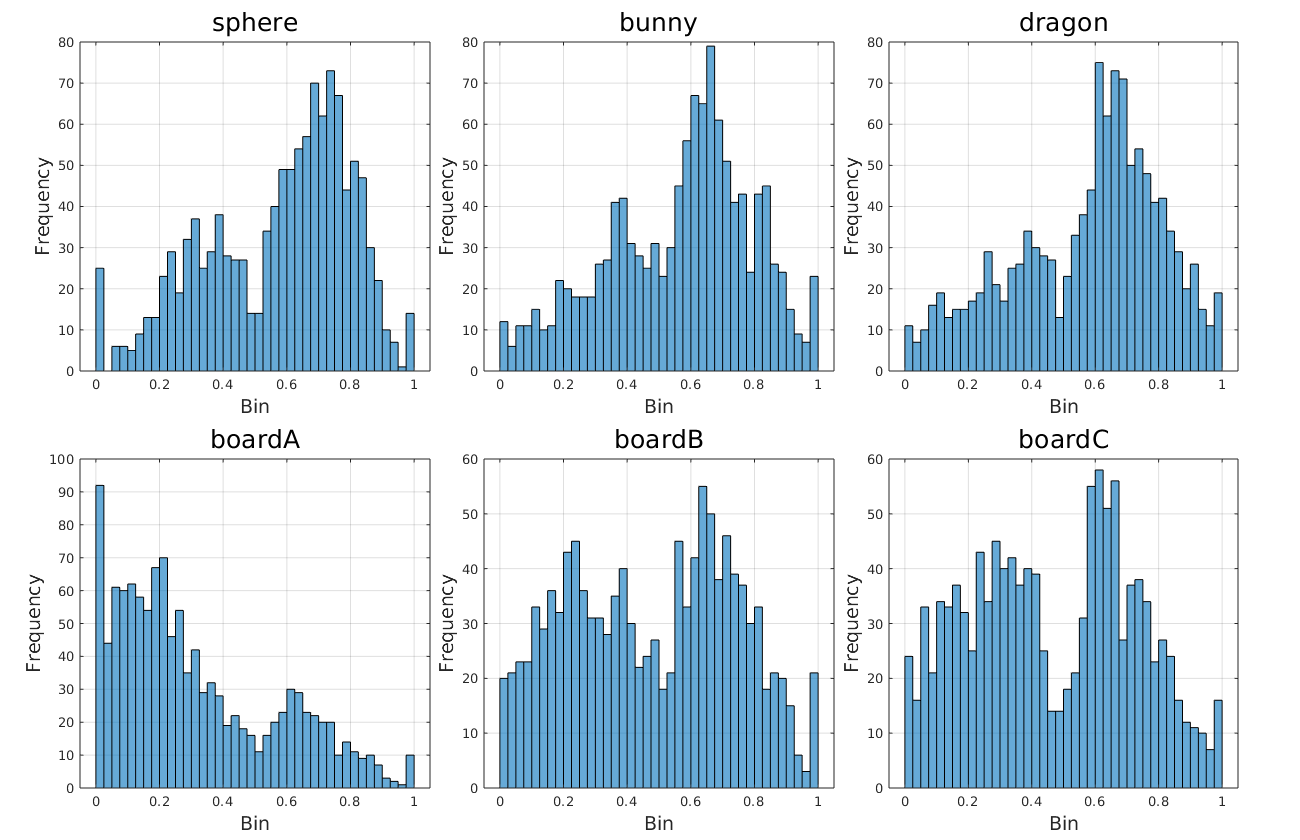

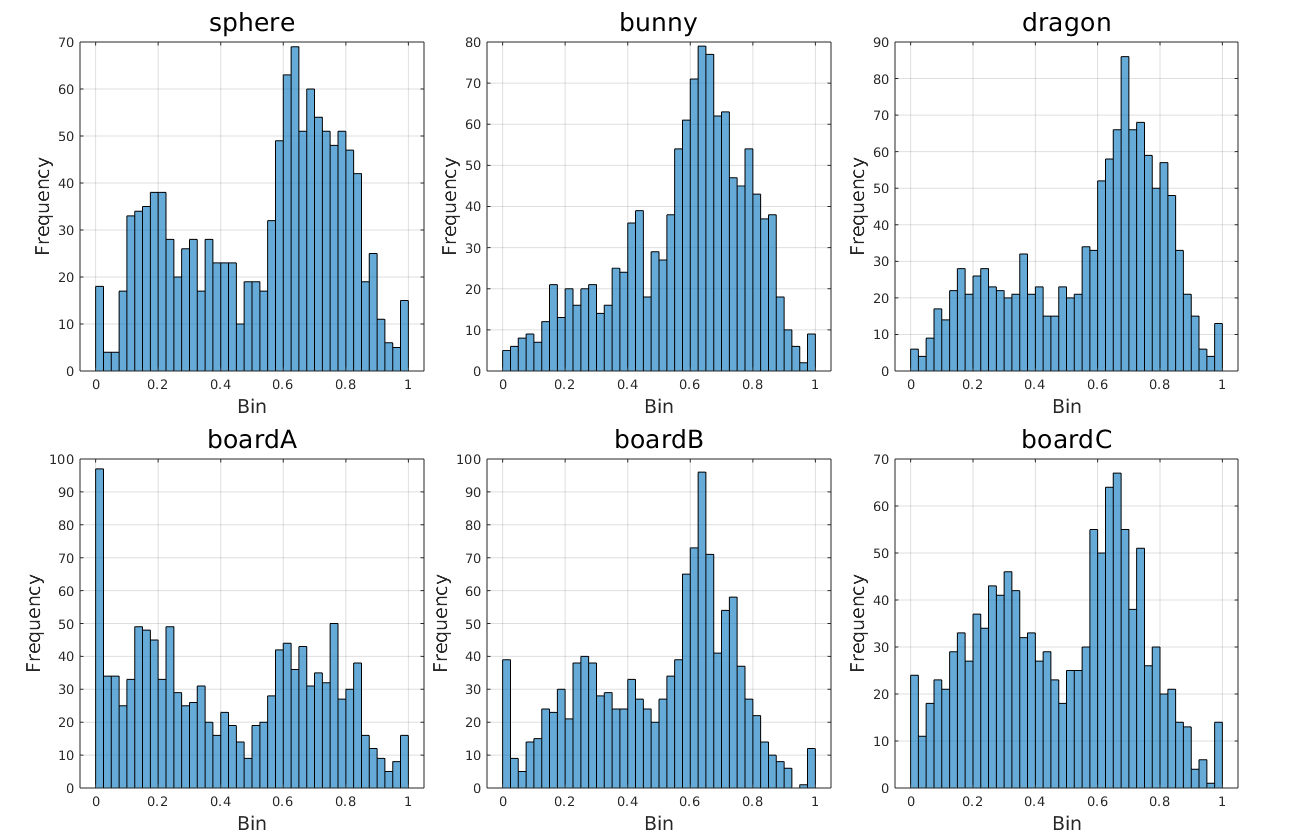

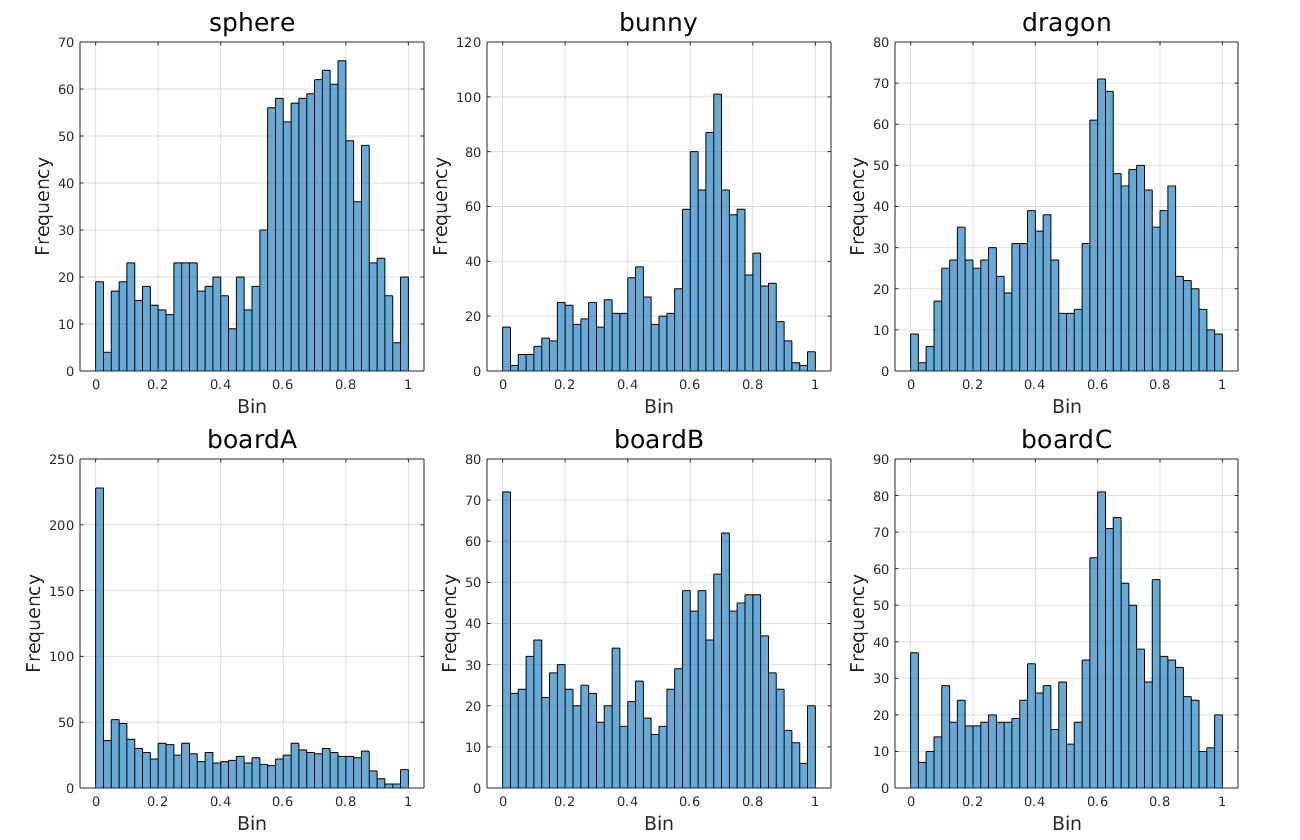

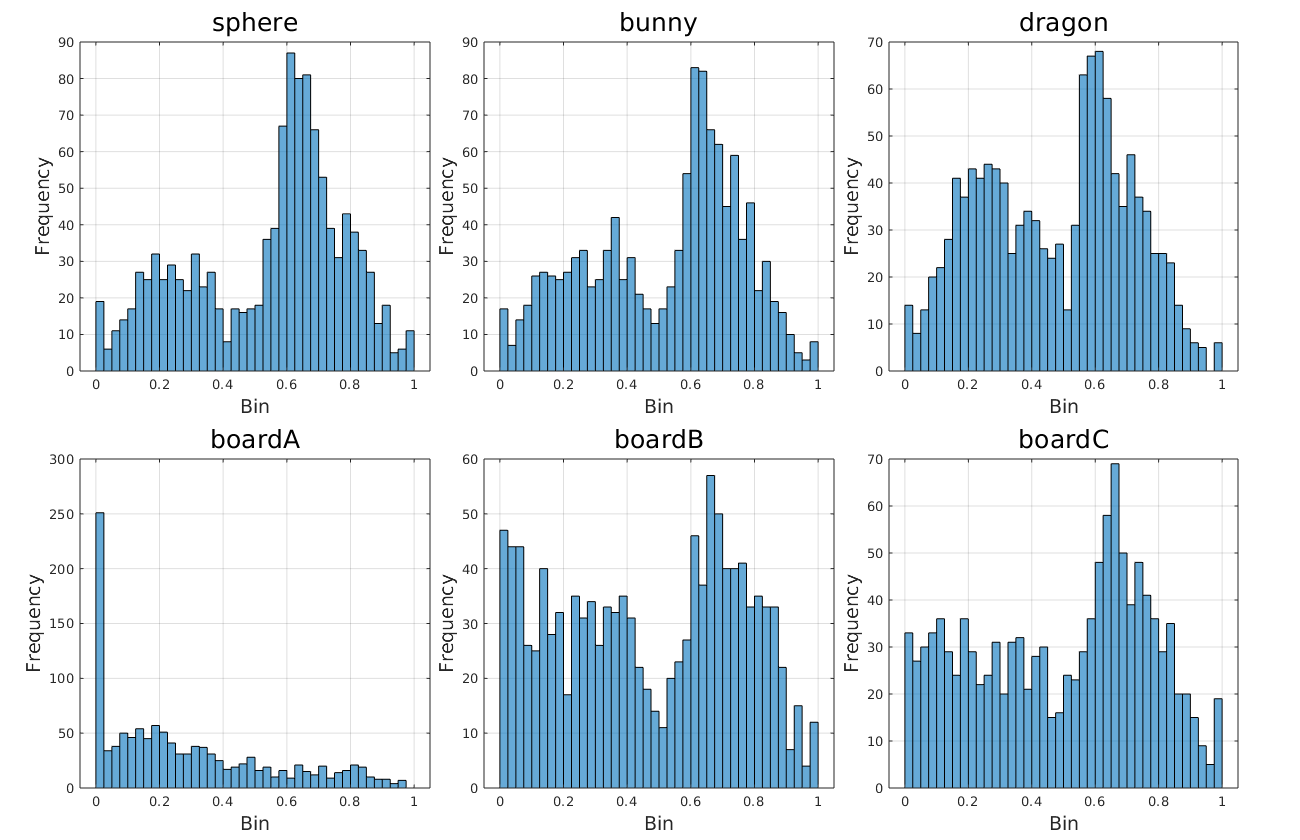

%---------------------------------------
% Exp4 光沢感応答 histgram HMS
%---------------------------------------
Exp4RowHMSPT_per = permute(Exp4HMSPT_Row,[2,3,1,4,5]);
Exp4RowHMSPT_reshape = reshape(Exp4RowHMSPT_per,size(Exp4RowHMSPT_per,1),size(Exp4RowHMSPT_per,2),[]);

%histgram
for mat = 1:size(Exp3HMS,2)
    figure('Position',[50,50,1300,840]);
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;
        values = Exp4RowHMSPT_reshape(mat,shape,:);

        histogram(values,'BinEdges',0:0.025:1);
        xlabel('Bin','FontSize',14); 
        ylabel('Frequency','FontSize',14);
        title(sprintf('%s',string(ShapeNames(shape))),'FontSize',19);
        grid on;
    end
    plotname = sprintf('%s/Exp4_bin_%s_Hist.jpg',ana_result,string(MatNames3(mat)));
    saveas(gcf, plotname);
end

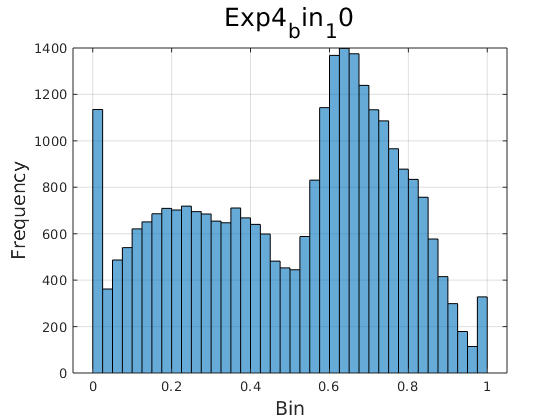

%---------------------------------------
% Exp4 光沢感応答 histgram 
%---------------------------------------
Exp4RowHMSPT_reshape = reshape(Exp4HMSPT_Row,[],1);

%histgram
figure
values = Exp4RowHMSPT_reshape(:);

histogram(values,'BinEdges',0:0.025:1);
xlabel('Bin','FontSize',14); 
ylabel('Frequency','FontSize',14);
title(sprintf('Exp4_bin_10'),'FontSize',19);
grid on;
plotname = sprintf('%s/Exp4_bin_all_9.jpg',ana_result);
saveas(gcf, plotname);

%-----------------------------------
% Exp3 vs Exp4 HDR coef
%-----------------------------------
amp = 1.5;
coef_list = zeros(size(Exp3H));
slop_list = zeros(size(Exp3H));

%散布図
figure;
graphtitle = sprintf('VRON GRI VS VROFF GRI');
Analysis_plot1(Exp3H(:),Exp4H(:),coef_list,slop_list, ...
    'VRON GRI','VROFF GRI',graphtitle,HDRNum_30,amp,1)
plotname = strcat(ana_result, '/VRONvsVROFF_HDR_Coef.jpg');
saveas(gcf, plotname);

%histgram
figure;
Analysis_histgram1(Exp3H(:),err_Exp3H(:),Exp4H(:),err_Exp4H(:), ...
    'HDR',HDRNum_30,'Normalized z-score',graphtitle,amp)
plotname = strcat(ana_result, '/VRONvsVROFF_inHMD_HDR_Hist.jpg');
saveas(gcf, plotname);

%-----------------------------------
% Exp3 vs Exp4 HDR,Material coef
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;

figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM,2)
    nexttile;
    Analysis_plot1(Exp3HM(:,mat),Exp4HM(:,mat),coef_list,slop_list, ...
        'VRON GRI','VROFF GRI',string(MatNames3(mat)),HDRNum_30,amp,predim)
end
plotname = strcat(ana_result, '/VRONvsVROFF_GRI_Mat_Coef.jpg');
saveas(gcf, plotname);

%histgram
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM,2)
    nexttile;
    Analysis_histgram1(Exp3HM(:,mat),err_Exp3HM(:,mat),Exp4HM(:,mat),err_Exp4HM(:,mat), ...
        'HDR',HDRNum_30,'Normalized z-score',string(MatNames3(mat)),amp)
end
plotname = strcat(ana_result, '/VRONvsVROFF_GRI_Mat_Hist.jpg');
saveas(gcf, plotname);


%-----------------------------------
% Exp3 vs Exp4 HDR,Shape 
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;

figure;
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS,2)
    nexttile;
    Analysis_plot1(Exp3HS(:,shape),Exp4HS(:,shape),coef_list,slop_list, ...
        'VRON GRI','VROFF GRI',string(ShapeNames(shape)),HDRNum_30,amp,predim);
end
plotname = strcat(ana_result, '/VRONvsVROFF_GRI_Shape_Coef.jpg');
saveas(gcf, plotname);


%histgram1
figure('Position',[50,50,1300,840]);
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS,2)
    nexttile;
    Analysis_histgram1(Exp3HS(:,shape),err_Exp3HS(:,shape),Exp4HS(:,shape),err_Exp4HS(:,shape), ...
        'HDR',HDRNum_30,'Normalized z-score',string(ShapeNames(shape)),amp)
end
plotname = strcat(ana_result, '/VRONvsVROFF_GRI_Shape_Hist.jpg');
saveas(gcf, plotname);

%---------------------------------------
% Exp3 光沢感応答 histgram HMS
%---------------------------------------
Exp3RowHMSPT_per = permute(Exp3HMSPT_Row,[2,3,1,4,5]);
Exp3RowHMSPT_reshape = reshape(Exp3RowHMSPT_per,size(Exp3RowHMSPT_per,1),size(Exp3RowHMSPT_per,2),[]);

%histgram
for mat = 1:size(Exp3HMS,2)
    figure('Position',[50,50,1300,840]);
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;
        values = Exp3RowHMSPT_reshape(mat,shape,:);

        histogram(values,'BinEdges',0:0.025:1);
        xlabel('Bin','FontSize',14); 
        ylabel('Frequency','FontSize',14);
        title(sprintf('%s',string(ShapeNames(shape))),'FontSize',19);
        grid on;
    end
    plotname = sprintf('%s/Exp3_bin_%s_Hist.jpg',ana_result,string(MatNames3(mat)));
    saveas(gcf, plotname);
end

%---------------------------------------
% Exp3 光沢感応答 histgram 
%---------------------------------------
Exp3RowHMSPT_reshape = reshape(Exp3HMSPT_Row,[],1);

%histgram
figure
values = Exp3RowHMSPT_reshape(:);

histogram(values,'BinEdges',0:0.025:1);
xlabel('Bin','FontSize',14); 
ylabel('Frequency','FontSize',14);
title(sprintf('VRGRI_bin_10'),'FontSize',19);
grid on;
plotname = sprintf('%s/VRGRI_bin_all_9.jpg',ana_result);
saveas(gcf, plotname);

%-----------------------------------
% VR vs 2D HDR,Material coef
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;

figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM,2)
    nexttile;
    Analysis_plot1(Exp3HM(:,mat),InoueHM(:,mat),coef_list,slop_list, ...
        'VR GRI','2D GRI',string(MatNames3(mat)),HDRNum_30,amp,predim)
end
plotname = strcat(ana_result, '/VRvs2D_Mat_Coef.jpg');
saveas(gcf, plotname);

%histgram
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM,2)
    nexttile;
    Analysis_histgram1(Exp3HM(:,mat),err_Exp3HM(:,mat),InoueHM(:,mat),err_InoueHM(:,mat), ...
        'HDR',HDRNum_30,'Normalized z-score',string(MatNames3(mat)),amp)
end
plotname = strcat(ana_result, '/VRvs2D_Mat_Hist.jpg');
saveas(gcf, plotname);

%-----------------------------------
% VR vs 2D HDR,Shape 
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;

figure;
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS,2)
    nexttile;
    Analysis_plot1(Exp3HS(:,shape),InoueHS(:,shape),coef_list,slop_list, ...
        'VR GRI','2D GRI',string(ShapeNames(shape)),HDRNum_30,amp,predim);
end
plotname = strcat(ana_result, '/VRvs2D_Shape_Coef.jpg');
saveas(gcf, plotname);


%histgram1
figure('Position',[50,50,1300,840]);
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS,2)
    nexttile;
    Analysis_histgram1(Exp3HS(:,shape),err_Exp3HS(:,shape),InoueHS(:,shape),err_InoueHS(:,shape), ...
        'HDR',HDRNum_30,'Normalized z-score',string(ShapeNames(shape)),amp)
end
plotname = strcat(ana_result, '/VRvs2D_Shape_Hist.jpg');
saveas(gcf, plotname);

%-----------------------------------
% VR vs 2D HDR,Material,Shape coef
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1;
predim = 1;

for mat = 1:size(Exp3HMS,2)
    figure;
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;

        graphtitle = sprintf('%s-%s',string(MatNames3(mat)),string(ShapeNames(shape)));
        Analysis_plot1(Exp3HMS(:,mat,shape),InoueHMS(:,mat,shape),coef_list,slop_list, ...
            'VR GRI','2D GRI',graphtitle,HDRNum_30,amp,predim)
    end
    plotname = sprintf('%s/VRvs2D_MS_%s_Coef.jpg',ana_result,string(MatNames3(mat)));
    saveas(gcf, plotname);
end

%histgram
for mat = 1:size(Exp3HMS,2)
    figure('Position',[50,50,1300,840]);
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;

        graphtitle = sprintf('%s-%s',string(MatNames3(mat)),string(ShapeNames(shape)));
        Analysis_histgram1(Exp3HMS(:,mat,shape),err_Exp3HMS(:,mat,shape), ...
            InoueHMS(:,mat,shape),err_InoueHMS(:,mat,shape), ...
            'HDR',HDRNum_30,'Normalized z-score',graphtitle,amp)
    end
    plotname = sprintf('%s/VRvs2D_MS_%s_Hist.jpg',ana_result,string(MatNames3(mat)));
    saveas(gcf, plotname);
end

%-----------------------------------
% VR vs 2D HDR coef
%-----------------------------------
amp = 1.5;
coef_list = zeros(size(Exp3H));
slop_list = zeros(size(Exp3H));

%散布図
figure;
graphtitle = sprintf('VR GRI VS 2D GRI');
Analysis_plot1(Exp3H(:),InoueH(:),coef_list,slop_list, ...
    'VR GRI','2D GRI',graphtitle,HDRNum_30,amp,1)
plotname = strcat(ana_result, '/VRvs2D_HDR_Coef.jpg');
saveas(gcf, plotname);

%histgram
figure;
Analysis_histgram1(Exp3H(:),err_Exp3H(:),InoueH(:),err_InoueH(:), ...
    'HDR',HDRNum_30,'Normalized z-score',graphtitle,amp)
plotname = strcat(ana_result, '/VRvs2D_HDR_Hist.jpg');
saveas(gcf, plotname);

%-----------------------------------
% VR vs LumModel HDR coef
%-----------------------------------
amp = 1.5;
coef_list = zeros(size(Exp3H));
slop_list = zeros(size(Exp3H));
predim = 1;

%散布図
figure;
graphtitle = sprintf('VR GRI VS 2D GRIModel');
Analysis_plot1(Exp3H(:),LumModelH(:),coef_list,slop_list, ...
    'VR GRI','2D GRIModel',graphtitle,HDRNum_30,amp,predim);
plotname = strcat(ana_result, '/VRvsLumModel_HDR_Coef.jpg');
saveas(gcf, plotname);

%histgram
figure;
Analysis_histgram1(Exp3H(:),err_Exp3H(:),LumModelH(:),Error_LumModelH(:), ...
    'HDR',HDRNum_30,'Normalized z-score',graphtitle,amp)
plotname = strcat(ana_result, '/VRvsLumModel_HDR_Hist.jpg');
saveas(gcf, plotname);

%-----------------------------------
% VR vs LumModel HDR coef
%-----------------------------------
amp = 1.5;
coef_list = [];
slop_list = [];
predim = 1;

%散布図
figure;
graphtitle = sprintf('VR GRI VS 2D GRIModel');
Analysis_plot1(Exp3H(:),LumModelH(:),coef_list,slop_list, ...
    'VR GRI','2D GRIModel',graphtitle,HDRNum_30,amp,predim);
plotname = strcat(ana_result, '/VRvsLumModel_HDR_Coef.jpg');
saveas(gcf, plotname);

%histgram
figure;
Analysis_histgram1(Exp3H(:),err_Exp3H(:),LumModelH(:),Error_LumModelH(:), ...
    'HDR',HDRNum_30,'Normalized z-score',graphtitle,amp)
plotname = strcat(ana_result, '/VRvsLumModel_HDR_Hist.jpg');
saveas(gcf, plotname);

%-----------------------------------
% VR vs LumModel HDR,Material,Shape coef
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1;
predim = 1;

for mat = 1:size(Exp3HMS,2)
    figure;
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;

        graphtitle = sprintf('%s-%s',string(MatNames3(mat)),string(ShapeNames(shape)));
        Analysis_plot1(Exp3HMS(:,mat,shape),LumModelH(:),coef_list,slop_list, ...
            'VR GRI','2D GRIModel',graphtitle,HDRNum_30,amp,predim);
    end
    plotname = sprintf('%s/VRvsLumModel_MS_%s_Coef.jpg',ana_result,string(MatNames3(mat)));
    saveas(gcf, plotname);
end

%-----------------------------------
% VR vs LumModel HDR,Shape 
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;

figure;
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS,2)
    nexttile;
    Analysis_plot1(Exp3HS(:,shape),LumModelH(:),coef_list,slop_list, ...
        'VR GRI','2D GRIModel',string(ShapeNames(shape)),HDRNum_30,amp,predim);
end
plotname = strcat(ana_result, '/VRvsLumModel_Shape_Coef.jpg');
saveas(gcf, plotname);


%histgram1
figure('Position',[50,50,1300,840]);
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS,2)
    nexttile;
    Analysis_histgram1(Exp3HS(:,shape),err_Exp3HS(:,shape),LumModelH(:),Error_LumModelH(:), ...
        'HDR',HDRNum_30,'Normalized z-score',string(ShapeNames(shape)),amp);
end
plotname = strcat(ana_result, '/VRvsLumModel_Shape_Hist.jpg');
saveas(gcf, plotname);

%-----------------------------------
% VR vs LumModel HDR,Material coef
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;

figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM,2)
    nexttile;
    Analysis_plot1(Exp3HM(:,mat),LumModelH(:),coef_list,slop_list, ...
        'VR GRI','2D GRIModel',string(MatNames3(mat)),HDRNum_30,amp,predim);
end
plotname = strcat(ana_result, '/VRvsLumModel_Mat_Coef.jpg');
saveas(gcf, plotname);

%histgram
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM,2)
    nexttile;
    Analysis_histgram1(Exp3HM(:,mat),err_Exp3HM(:,mat),LumModelH(:),Error_LumModelH(:), ...
        'HDR',HDRNum_30,'Normalized z-score',string(MatNames3(mat)),amp)
end
plotname = strcat(ana_result, '/VRvsLumModel_Mat_Hist.jpg');
saveas(gcf, plotname);

%-----------------------------------
% 2D vs LumModel HDR coef
%-----------------------------------
amp = 1.5;
coef_list = [];
slop_list = [];
predim = 1;

%散布図
figure;
graphtitle = sprintf('2D GRI VS 2D GRIModel');
Analysis_plot1(InoueH(:),LumModelH(:),coef_list,slop_list, ...
    '2D GRI','2D GRIModel',graphtitle,HDRNum_30,amp,predim);
plotname = strcat(ana_result, '/2DvsLumModel_HDR_Coef.jpg');
saveas(gcf, plotname);

%histgram
figure;
Analysis_histgram1(InoueH(:),err_InoueH(:),LumModelH(:),Error_LumModelH(:), ...
    'HDR',HDRNum_30,'z-score',graphtitle,amp)
plotname = strcat(ana_result, '/2DvsLumModel_HDR_Hist.jpg');
saveas(gcf, plotname);

%-----------------------------------
% 2D vs LumModel HDR,Material,Shape coef
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1;
predim = 1;

for mat = 1:size(InoueHMS,2)
    figure;
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(InoueHMS,3)
        nexttile;

        graphtitle = sprintf('%s-%s',string(MatNames3(mat)),string(ShapeNames(shape)));
        Analysis_plot1(InoueHMS(:,mat,shape),LumModelH(:),coef_list,slop_list, ...
            '2D GRI','2D GRIModel',graphtitle,HDRNum_30,amp,predim);
    end
    plotname = sprintf('%s/2DvsLumModel_MS_%s_Coef.jpg',ana_result,string(MatNames3(mat)));
    saveas(gcf, plotname);
end

%-----------------------------------
% VR vs ObjModelNorm HDR coef
%-----------------------------------
amp = 1.5;
coef_list = [];
slop_list = [];
Error_ObjModelH = zeros(size(ObjModelH));
predim = 1;

%散布図
figure;
graphtitle = sprintf('VR GRI VS 2D ObjGRIModel');
Analysis_plot1(Exp3H(:),ObjModelH(:),coef_list,slop_list, ...
    'VR GRI','2D ObjGRIModel',graphtitle,HDRNum_30,amp,predim);
plotname = strcat(ana_result, '/VRvsObjNormModel_HDR_Coef.jpg');
saveas(gcf, plotname);

%histgram
figure;
Analysis_histgram1(Exp3H(:),err_Exp3H(:),ObjModelNormH(:),Error_ObjModelH(:), ...
    'HDR',HDRNum_30,'Normalized z-score',graphtitle,amp)
plotname = strcat(ana_result, '/VRvsObjNormModel_HDR_Hist.jpg');
saveas(gcf, plotname);

%-----------------------------------
% VR vs ObjModel HDR coef
%-----------------------------------
amp = 1.5;
coef_list = [];
slop_list = [];
Error_ObjModelH = zeros(size(ObjModelH));
predim = 1;

%散布図
figure;
graphtitle = sprintf('VR GRI VS 2D ObjGRIModel');
Analysis_plot1(Exp3H(:),ObjModelH(:),coef_list,slop_list, ...
    'VR GRI','2D ObjGRIModel',graphtitle,HDRNum_30,amp,predim);
plotname = strcat(ana_result, '/VRvsObjModel_HDR_Coef.jpg');
saveas(gcf, plotname);

%histgram
figure;
Analysis_histgram1(Exp3H(:),err_Exp3H(:),ObjModelH(:),Error_ObjModelH(:), ...
    'HDR',HDRNum_30,'Normalized z-score',graphtitle,amp)
plotname = strcat(ana_result, '/VRvsObjModel_HDR_Hist.jpg');
saveas(gcf, plotname);

%-----------------------------------
% VR vs ObjModel HDR,Material,Shape coef
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1;
predim = 1;

for mat = 1:size(Exp3HMS,2)
    figure;
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;
        graphtitle = sprintf('%s-%s',string(MatNames3(mat)),string(ShapeNames(shape)));
        Analysis_plot1(Exp3HMS(:,mat,shape),ObjModelHMS(:,mat,shape),coef_list,slop_list, ...
            'VR GRI','2D ObjGRIModel',graphtitle,HDRNum_30,amp,predim)
    end
    plotname = sprintf('%s/VRvsObjModel_MS_%s_Coef.jpg',ana_result,string(MatNames3(mat)));
    saveas(gcf, plotname);
end

%-----------------------------------
% exp1,2 VS Hist
%-----------------------------------
%Exp1
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;
%plot
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp1ThHM15,2)
    nexttile;
    Analysis_plot1(Exp1ThHM15(:,mat),Exp1MiHM15(:,mat),coef_list,slop_list, ...
        'ThreeJS GRI','Mitsuba GRI',string(MatNames3(mat)),HDRNum_15,amp,predim);
end
plotname = strcat(ana_result, '/ThreeJSvsMitsuba_Mat_Coef.jpg');
saveas(gcf, plotname);
%histgram
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp1ThHM15,2)
    nexttile;
    Analysis_histgram1(Exp1ThHM15(:,mat),err_Exp1ThHM15(:,mat),Exp1MiHM15(:,mat),err_Exp1MiHM15(:,mat), ...
        'HDR',HDRNum_15,'Normalized z-score',string(MatNames3(mat)),amp)
end
plotname = strcat(ana_result, '/ThreeJSvsMitsuba_Mat_Hist.jpg');
saveas(gcf, plotname);


%Exp2
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;
%plot
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp2MiHM15,2)
    nexttile;
    Analysis_plot1(Exp1MiHM15(:,mat),Exp2MiHM15(:,mat),coef_list,slop_list, ...
        'Thurston GRI','Magnitude GRI',string(MatNames3(mat)),HDRNum_15,amp,predim);
end
plotname = strcat(ana_result, '/ThurstonvsMagnitude_Mat_Coef.jpg');
saveas(gcf, plotname);
%histgram
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp2MiHM15,2)
    nexttile;
    Analysis_histgram1(Exp1MiHM15(:,mat),err_Exp1MiHM15(:,mat),Exp2MiHM15(:,mat),err_Exp2MiHM15(:,mat), ...
        'HDR',HDRNum_15,'Normalized z-score',string(MatNames3(mat)),amp)
end
plotname = strcat(ana_result, '/ThurstonvsMagnitude_Mat_Hist.jpg');
saveas(gcf, plotname);

%-----------------------------------
% exp1,2 VS　Plot
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1.5;
dim = 1;

%Exp1
figure;
graphtitle = sprintf('ThreeJS GRI VS Mitsuba GRI');
Analysis_plot1(Exp1ThH15(:),Exp1MiH15(:),coef_list,slop_list, ...
    'ThreeJS GRI','Mitsuba GRI',graphtitle,HDRNum_15,amp,dim)
plotname = strcat(ana_result, '/ThreeJS vs Mitsuba_GRI.jpg');
saveas(gcf, plotname);

%Exp2
figure;
graphtitle = sprintf('Magnitude GRI VS Thurston GRI');
Analysis_plot1(Exp2MiH15(:),Exp1MiH15(:),coef_list,slop_list, ...
    'Magnitude GRI','Thurston GRI',graphtitle,HDRNum_15,amp,dim)
plotname = strcat(ana_result, '/Magnitude vs Thurston_GRI.jpg');
saveas(gcf, plotname);

%-----------------------------------
% exp1,exp2 VS VR HDR,material
%-----------------------------------
name1 = 'Exp1';
name2 = 'Exp2';
name3 = 'Exp3';
title = 'Exp2vsExp3_HM';
Make_2dims_vsgraph_Coef_Hist(Exp3HM15,err_Exp3HM15,Exp2ThHM15,err_Exp2ThHM15,title,name3,name2);
title = 'Exp2vsExp3_HDR';
Make_1dims_vsgraph_Coef_Hist(Exp3H15,err_Exp3H15,Exp2ThH15,err_Exp2ThH15,title,name3,name2);
title = 'Exp1vsExp3_HM';
Make_2dims_vsgraph_Coef_Hist(Exp3HM15,err_Exp3HM15,Exp1ThHM15,err_Exp1ThHM15,title,name3,name1);
title = 'Exp1vsExp3_HDR';
Make_1dims_vsgraph_Coef_Hist(Exp3H15,err_Exp3H15,Exp1ThH15,err_Exp1ThH15,title,name3,name1);

%-----------------------------------
% exp1,exp2 VS Old HDR,material
%-----------------------------------
name1 = 'Exp1';
name2 = 'Exp2';
name3 = 'Old';
errorinoue1 = zeros(size(InoueHM15));
errorinoue2 = zeros(size(InoueH15));

title = 'Exp2vsOld_HM';
Make_2dims_vsgraph_Coef_Hist(InoueHM15,errorinoue1,Exp2MiHM15,err_Exp2MiHM15,title,name3,name2);
title = 'Exp2vsOld_HDR';
Make_1dims_vsgraph_Coef_Hist(InoueH15,errorinoue2,Exp2MiH15,err_Exp2MiH15,title,name3,name2);
title = 'Exp1vsOld_HM';
Make_2dims_vsgraph_Coef_Hist(InoueHM15,errorinoue1,Exp1MiHM15,err_Exp1MiHM15,title,name3,name1);
title = 'Exp1vsOld_HDR';
Make_1dims_vsgraph_Coef_Hist(InoueH15,errorinoue2,Exp1MiH15,err_Exp1MiH15,title,name3,name1);

%{
%-----------------------------------
% Exp3 Material Shape
%-----------------------------------
for mat = 1:size(Exp3HMS,2)
    figure;
    hold on;
    for shape = 1:size(Exp3HMS,3)
        subplot(2, 3, shape);
        bar_width = 0.35;
        x = 1:length(HDRNames);
    
        bar(x + bar_width/2, Exp3HMS(:,mat, shape), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
        errorbar(x + bar_width/2, Exp3HMS(:,mat,shape), err_Exp3HMS(:,mat,shape), 'k', 'linestyle', 'none');
    
        ylim([-1.2 1.2]);
        set(gca, 'XTick', 1:length(HDRNames3));
        set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
        xlabel('HDR', 'FontSize', 16); 
        ylabel('Average z-score', 'FontSize', 16);
        title(['compare of ' MatNames2{mat} '&' ShapeNames{shape}], 'FontSize', 16);
        %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
    end
    plotname = strcat(ana_result, '/Exp3_MS_', MatNames2{mat},'.jpg');
    saveas(gcf, plotname);
    hold off;
end

%-----------------------------------
% Exp3 Material
%-----------------------------------
figure;
hold on;
for mat = 1:4
    subplot(2, 2, mat);
    bar_width = 0.35;
    x = 1:length(HDRNames);

    bar(x + bar_width/2, Exp3HM(:,mat), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, Exp3HM(:,mat), error_Exp3HMSNorm(:,mat), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(HDRNames3));
    set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' MatNames2{row}], 'FontSize', 16);
    %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
end
plotname = strcat(ana_result, '/Exp3_Material', '.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Exp3 Shape
%-----------------------------------
figure;
hold on;
for shape = 1:size(Exp3HS,2)
    subplot(2,3,shape);
    bar_width = 0.35;
    x = 1:length(HDRNames);

    bar(x + bar_width/2, Exp3HS(shape, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, Exp3HS(shape, :), error_Exp3HSNorm(shape,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(HDRNames3));
    set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' ShapeNames{shape}], 'FontSize', 16);
    %legend([b2,b3],{'2D','3D'}, 'Location', 'best');

end
plotname = strcat(ana_result, '/Exp3_', 'Shape','.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Exp3 HDR
%-----------------------------------
figure;
hold on;
bar_width = 0.35;
x = 1:length(HDRNames);
avb = bar(x + bar_width/2, Exp3H, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
avh = errorbar(x + bar_width/2, Exp3H, error_Exp3HNorm, 'k', 'linestyle', 'none');
ylim([-1.2 1.2]);
set(gca, 'XTick', 1:length(HDRNames3));
set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
xlabel('HDR', 'FontSize', 16); 
ylabel('Normalized z-score', 'FontSize', 16);
title('HDR', 'FontSize', 16);
plotname = strcat(ana_result, '/Exp3_HDR.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue material
%-----------------------------------
figure;
hold on;
for mat = 1:size(InoueHM,2)
    subplot(2,2,mat);
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, InoueMHNorm(:,mat), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    %h3 = errorbar(x + bar_width/2, InoueMHNorm(:,row), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' InoueMatname{mat}], 'FontSize', 16);
end
plotname = strcat(ana_result, '/Old_Material','.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue Shape
%-----------------------------------
figure;
hold on;
for shape = 1:size(InoueHS,2)
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, InoueSHNorm(:,shape), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    %h3 = errorbar(x + bar_width/2, InoueSHNorm(:,row), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Normalized z-score', 'FontSize', 16);
    title(['compare of ' InoueShapeName{shape}], 'FontSize', 16);
end
plotname = strcat(ana_result, '/Old_Shape', '.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue material shape
%-----------------------------------
for mat = 1:size(InoueHMS,2)
    figure;
    hold on;
    for shape = 1:size(InoueHMS,3)
        subplot(2,3,shape);
        bar_width = 0.35;
        x = 1:length(HDRNames);
    
        bar(x + bar_width/2, InoueHMS(:,mat, shape), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
        %errorbar(x + bar_width/2, InoueMHSNorm(:,matnum, shapenum), error_Exp3MHS(matnum,:,shapenum), 'k', 'linestyle', 'none');
    
        ylim([-1.2 1.2]);
        set(gca, 'XTick', 1:length(HDRNames3));
        set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
        xlabel('HDR', 'FontSize', 16); 
        ylabel('Average z-score', 'FontSize', 16);
        title(['compare of ' InoueMatname{mat} '&' InoueShapeName{row}], 'FontSize', 16);
        %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
    end
    plotname = strcat(ana_result, '/Old_MS_', InoueMatname{mat},'.jpg');
    saveas(gcf, plotname);
    hold off;
end
%}

%{
%-----------------------------------
% Exp3 vs Old HDR coef
%-----------------------------------
Exp3HMS_reshaped = reshape(Exp3HMS,size(Exp3HMS,1),[]);
InoueHMS_reshaped = reshape(InoueHMS,size(InoueHMS,1),[]);

coef_list = zeros(size(Exp3H));
slop_list = zeros(size(Exp3H));
amp = 1.0;

% coef and slope
for hdr = 1:size(Exp3H)
    x = Exp3HMS(hdr,:,:);
    y = InoueHMS(hdr,:,:);
    r = corrcoef(x,y);
    r_value = r(1,2);
    coef_list(hdr) = r_value;
    p = polyfit(x,y,1);
    slop_list(hdr) = p(1);
end

% coef hisgram
figure;
hold on;
x = 1:length(coef_list);
bar_width = 0.4;
bar_coef = bar(x,coef_list,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');
%bar_coef = bar(x - bar_width/2,coef_list,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');
%bar_slope = bar(x + bar_width/2,slop_list,bar_width, 'FaceColor', 'r', 'DisplayName', 'Slope');
for i = 1:length(coef_list)
    graphtext1 = sprintf('%.2f',coef_list(i));
    text(i,(abs(coef_list(i))+0.06)*coef_list(i)/abs(coef_list(i)),graphtext1,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',8*amp);
    %graphtext2 = sprintf('%.2f',slop_list(i));
    %text(i + bar_width/2,slop_list(i),graphtext2,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
end
ylim([-0.55 1.0]);
set(gca, 'XTick', x);
xticklabels(HDRNames3);
set(gca,'FontSize',8*amp);
xlabel('HDR','FontSize',18*amp);
ylabel('Coef','FontSize',18*amp);
title(sprintf('VR VS 2D Coef about HDR'),'FontSize',18*amp);
%legend([bar_coef, bar_slope], {'Coef', 'Slope'}, 'Location', 'best','Orientation','vertical');
legend(bar_coef, 'Coef', 'Location', 'northeast','Orientation','vertical');
text(0,0.95, '* : p-value < 0.05', 'FontSize', 15*amp);
grid on;
hold off;
plotname = strcat(ana_result, '/Exp3vsOld_HDR_Coefbar.jpg');
saveas(gcf, plotname);
%}

%{
%-----------------------------------
% Exp3 vs Old all coef
%-----------------------------------
amp = 1.5;

%散布図
figure;
x = Exp3H(:);
y = InoueH(:);
r = corrcoef(x,y);
r_value = r(1,2);
p = polyfit(x,y,1);
p_fit = polyval(p,x);

scatter(x,y,'filled');
hold on;
%plot(x,p_fit,'r-','LineWidth',1.5);

xlim([-1.5 1.0]);
x_limits = xlim;
%ylim([-1.2 1.2]);
y_limits = ylim;
common_limits = [min([x_limits, y_limits]), max([x_limits, y_limits])];
plot(common_limits, common_limits, 'r--', 'LineWidth', 2);
% グラフ囲む
rectangle('Position', [x_limits(1), y_limits(1), diff(x_limits), diff(y_limits)], ...
          'EdgeColor', 'k', 'LineWidth', 0.75);
% HDR No
for point = 1:length(x)
    text(x(point)-0.01, y(point)+0.01, num2str(HDRNames3(point)), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right','FontSize',8*amp);
end
hold off;

text(x_limits(1)*0.95,y_limits(2)*0.95, 'Luminance image No.', 'FontSize', 8*amp);
set(gca,'FontSize',8*amp);
xlabel('VR Z-score','FontSize',12*amp);
ylabel('2D Z-score','FontSize',12*amp);
%title(sprintf('VR VS 2D Glossness\n correlation coefficient : %.2f,Slope : %.2f', r_value,p(1)));
title(sprintf('VR VS 2D Glossness\n correlation coefficient : %.2f', r_value),'FontSize',10*amp);
grid on;
plotname = strcat(ana_result, '/Exp3vsOld_HDR_Coef.jpg');
saveas(gcf, plotname);


%histgram2
bar1 = Exp3H(:);
err1 = err_Exp3H(:);
bar2 = InoueH(:);

figure;
bar_width = 0.35;
x = 1:length(HDRNames);

hold on;
bar_exp3 = bar(x + bar_width/2, bar1, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
errorbar(x + bar_width/2, bar1, err1, 'k', 'linestyle', 'none');
bar_old = bar(x - bar_width/2, bar2, bar_width, 'FaceColor', 'r', 'DisplayName', '3D'); 
%errorbar(x - bar_width/2, InoueHSNorm, error_Exp3HSNorm, 'k', 'linestyle', 'none');
hold off;

ylim([-1.2 1.2]);
set(gca, 'XTick', x);
xticklabels(HDRNames3);
xtickangle(90);
set(gca,'FontSize',6*amp);

xlabel('HDR','FontSize',12*amp); 
ylabel('Normalized z-score','FontSize',12*amp);
title(sprintf('HDR: Coef = %.2f,Slope = %.2f', r_value,p(1)),'FontSize',12*amp);
legend([bar_exp3, bar_old], {'VR', '2D'}, 'Location', 'southeast','Orientation','vertical');
legend('boxoff');
grid on;
plotname = strcat(ana_result, '/Exp3vsOld_HDR_Hist.jpg');
saveas(gcf, plotname);
%}

%{
% coef hisgram
figure;
hold on;
x = 1:length(coef_list);
bar_width = 0.4;
bar_coef = bar(x,coef_list,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');
%bar_coef = bar(x - bar_width/2,coef_list,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');
%bar_slope = bar(x + bar_width/2,slop_list,bar_width, 'FaceColor', 'r', 'DisplayName', 'Slope');
for i = 1:length(coef_list)
    graphtext1 = sprintf('%.2f',coef_list(i));
    text(i - bar_width/2,coef_list(i),graphtext1,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
    %graphtext2 = sprintf('%.2f',slop_list(i));
    %text(i + bar_width/2,slop_list(i),graphtext2,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
    if S_p_value(i) < 0.05
        graphtext3 = sprintf('*');
        text(i,max(coef_list(i),slop_list(i))+0.05,graphtext3,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
    end
end
ylim([0 1.0]);
set(gca, 'XTick', x);
xticklabels(ShapeNames);
set(gca,'FontSize',12*amp);
xlabel('Shape types','FontSize',18*amp);
ylabel('Value','FontSize',18*amp);
title(sprintf('VR VS 2D Coef about Shape'),'FontSize',18*amp);
%legend([bar_coef, bar_slope], {'Coef', 'Slope'}, 'Location', 'best','Orientation','vertical');
legend(bar_coef, 'Coef', 'Location', 'best','Orientation','vertical');
text(0,0.95, '* : p-value < 0.05', 'FontSize', 15*amp);
hold off;
plotname = strcat(ana_result, '/Exp3vsOld_Shape_Coefbar.jpg');
saveas(gcf, plotname);
%}
